%%通过RS structure提取diff中的body的剂量差异信息并存储到mat文件中用于后期深度学习

%%%执行该代码前 应现将Doss-diff和对应需要提取的勾画结构信息Rt structure放置于同一个文件夹内
close
clear
close all

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%创建后面剂量差异信息的文件命名格式
FileName=["LAT-1mmL";"LAT-1mmR";"Lng-1mmF";"Lng-1mmH";"Vrt-1mmA";"Vrt-1mmP"...
    ;"MU3%-";"MU3%";"MU5%-";"MU5%";"p1--0.2G";"p1--0.4G";"p1-0.2G";"p1-0.4G"...
    ;"p1--0.5X2F";"p1--1X2F";"p1-0.5X2F";"p1-1X2F";"p1-0.5X2R";"p1-1X2R";"p1-2X2R"...
    ;"AAA-AXBW";"p1-AAA";"p1-AXBW";"p1-body0.5";"p1-body1.5";"p1-body1"];

FileName_SIZE=size(FileName,1);%获取文件名数组的长度

%7分类问题
SETUP = ["LAT-1mmL";"LAT-1mmR";"Lng-1mmF";"Lng-1mmH";"Vrt-1mmA";"Vrt-1mmP"];
MU = ["MU3%-";"MU3%";"MU5%-";"MU5%"];
MLCR = ["p1-0.5X2R";"p1-1X2R";"p1-2X2R"];
MLCS = ["p1--0.5X2F";"p1--1X2F";"p1-0.5X2F";"p1-1X2F"];
GANTRY = ["p1--0.2G";"p1--0.4G";"p1-0.2G";"p1-0.4G"];
ErrorFree = ["AAA-AXBW";"p1-AAA";"p1-AXBW"];
BodyChanges = ["p1-body0.5";"p1-body1.5";"p1-body1"];

%%%打开文件选择病人ID的文件夹中的任意文件即可
[filename,filepath]=uigetfile('*.*','Please select a file to improt','E:\医学物理\待投稿论文\Dosiomics\dosiomics_Data');
%只搜索RD文件
filetype='*.dcm';
searchmode=fullfile(filepath,filetype);
folders=dir(searchmode);
folder_len=size(folders,1);%获取文件目录长度

%遍历文件  找到ori_dose的路径
for i=1:folder_len
    if contains(folders(i).name,'RS')
        filename = fullfile(folders(i).folder,folders(i).name);
        %fprintf('正在读取 DICOM 文件 %s\n', filename)
 
        %{ 
          **`UseVRHeuristic`参数**：当设置为`false`时，MATLAB将严格按照DICOM标准解析文件，而不尝试猜测VR类型。
         这可以避免因启发式方法导致的错误。**影响**：关闭启发式方法可能会使MATLAB无法读取一些不符合标准但实际可读的文件。
         但对于大多数标准文件，这样设置没有问题。**其他注意事项**：如果文件确实不符合标准，可能需要使用第三方工具修复DICOM文件。
        %}
        RSinfo=dicominfo(filename,UseVRHeuristic=false); %读取RS文件 如果警告：字节 1679728 处的属性(3006,0040)可能错误地解释为显式 VR建使用此代码
        %RSinfo=dicominfo(filename);

        %记住RS当前的行号信息
        rs_row_to_delete=i;
    end
end
folders(rs_row_to_delete) = [];  %删除当前的RS的文件目录，只剩下dose文件

%读取剂量Rstructure文件 获取roi的结构信息
Coutours=dicomContours(RSinfo);
ROIs=Coutours.ROIs;  %获取ROT信息
ROI_name=ROIs.Name;  %获取勾画结构名称
CountourData=ROIs.ContourData;%获取勾画信息

%%选择提取特征的ROI
selectROI='Body';
ROI_index=contains(ROI_name,selectROI,"IgnoreCase",true); %返回逻辑数组 是否包含body字符串
positions = find(ROI_index);%返回body字符串的位置

%获取ROI body的轮廓数据
RoiCountour=CountourData{positions};
ID = RSinfo.PatientID;  %获取病人信息

folder_len_new = size(folders,1);%由于存在RS文件删除，更新文件目录长度

for foldersize = 1:folder_len_new
    %逐个读取文件信息获得文件名
    dosefile = fullfile(folders(foldersize).folder,folders(foldersize).name);
    
    %读取当前路径剂量文件的信息，以便于生成掩模
    ori_info = dicominfo(dosefile);
    Data_ori=squeeze(dicomread(ori_info)); %获取data数据并去除为1的维度
    Dose_ori=double(Data_ori)*ori_info.DoseGridScaling;%获取剂量数据
    
    %验证dose和rs是否在同一坐标
    RSAxes = RSinfo.ReferencedFrameOfReferenceSequence.Item_1.FrameOfReferenceUID;
    RDAxes = ori_info.FrameOfReferenceUID;

    %判断是否同一坐标系 否则报错
    if ~strcmp(RSAxes,RDAxes)
        fprintf('坐标系不匹配');
    end

    %%读取剂量数据文件
    dose_spacing(1:2) = ori_info.PixelSpacing;  %xy轴的像素间距
    dose_spacing(3) = abs(ori_info.GridFrameOffsetVector(2) - ori_info.GridFrameOffsetVector(1));  %获取层厚
    dose_origin = ori_info.ImagePositionPatient;  %原始图像位置(X,Y,Z)
    dose_size = size(Dose_ori);%获取剂量文件尺寸

    %剂量数据的坐标
    x_dose = zeros(dose_size(2),1);
    y_dose = zeros(dose_size(1),1);
    z_dose = zeros(dose_size(3),1);

    %对齐坐标
    for a = 1:dose_size(2)
        x_dose(a) = dose_origin(1) + dose_spacing(1)*(a-1);    %x轴坐标实际位置
    end

    for b = 1:dose_size(1)
        y_dose(b) = dose_origin(2) + dose_spacing(2)*(b-1);    %y轴坐标实际位置
    end

    for c = 1:dose_size(3)
        z_dose(c) = dose_origin(3) + dose_spacing(3)*(c-1);    %z轴坐标实际位置
    end

    %基于ori dose文件初始化Mask掩模
    bodyMask = false(dose_size);

    %获取roi层面
    roi_slice = numel(RoiCountour); %获取ROI的最终层面数目 

    for slice = 1:roi_slice
        zpos = RoiCountour{slice}(1,3); %获取ROI的z轴位置 因为每个层面的z轴一致  因此选择任意一个第三列可以获得z轴最表
        slicecontours = RoiCountour{slice}(:,1:2);%提取勾画数据
        [~,dosesliceidx] = min(abs(z_dose-zpos)); %获取距离当前勾画平面的最近的剂量数据平面

        %%获取当前层面的point数目
        pointidx =  height(slicecontours);

        %初始化需要放置每个像素位置的坐标值向量
        xpixels = zeros(pointidx,1);
        ypixels= zeros(pointidx,1);
    
        for pdx= 1:pointidx  %遍历层面上的每个点
            %%获取层面的xy的物理坐标值
        
            xpoints = slicecontours(pdx,1);
            ypoints = slicecontours(pdx,2);
        
            %转换为像素坐标
            xpixels(pdx) = (xpoints-dose_origin(1))/dose_spacing(1)+1;
            ypixels(pdx) = (ypoints-dose_origin(2))/dose_spacing(2)+1;
        end

        sliceMask = poly2mask(xpixels,ypixels,dose_size(1),dose_size(2));%建立当前层面的掩模

        %添加到3D掩模
        bodyMask(:,:,dosesliceidx) = bodyMask(:,:,dosesliceidx)|sliceMask; %求并集
    end

    %fullMask = bodyMask; %可以复制掩模备份 本次直接在bodyMask上进行操作
    % 由于腹部剂量5mm一层，但是剂量网格为2.5mmm，层厚差异会导致每间隔一层掩模 部分缺失的掩模用于后续插值

    %获取roi层面
    roimat = cell2mat(RoiCountour); %转换为mat
    uniqueslice = unique(roimat(:,3)); %获取不重复的z轴层面位置
    rs_slice = numel(uniqueslice); %获取勾画结构ROI的最终层面数目 

    [~,~,numSlices] =size(bodyMask);   %获取实际掩模层数
    slice_status = false(1,numSlices);  %状态向量 确认当前层面是否存在掩模
    roi_slice_idx = zeros(rs_slice,1);  %初始化向量用于保存ROI结构在实际剂量层面的层面索引

    for sidx = 1:rs_slice  %%遍历每个ROI的层面
        [~,sliceidx] = min(abs(z_dose-uniqueslice(sidx)));  %获取勾画层在剂量数据的层面索引
        roi_slice_idx(sidx) = sliceidx; %保存于roi_slice_idx中
        slice_status(sliceidx) = true;  %确认当前层面中存在勾画结构的掩模
    end

    %按顺序处理每个ROI切片
    roi_slice_idx = sort(roi_slice_idx); %排序

    for ii = 1:length(roi_slice_idx)-1
        start_idx = roi_slice_idx(ii);%初始层面位置
        end_idx = roi_slice_idx(ii+1);%后续层面位置

        %计算两个层面的位置
        slice_gap =end_idx - start_idx;

        slice1 = bodyMask(:,:,start_idx); %获取初始层面的掩模信息
        slice2 = bodyMask(:,:,end_idx); %获取后续层面的掩模信息

        if slice_gap == 2  %正常间隔 2层缺失1层掩模 当掩模缺失才会发生 只有腹部剂量才会触发
            mid_idx = start_idx + 1;
        
            %距离变换插值插值法 补全掩模  
            % 计算到每个层面边界的距离
            D1 = bwdist(~slice1);
            D2 = bwdist(~slice2);

            D_interp = 0.5*D1 +0.5*D2;
            interplated = D_interp>0; %当D_interp中的值大于0时 设置为目标 否则为背景

            bodyMask(:,:,mid_idx) = interplated;
        end
    end

     
    %形态学滤波 填充Mask中的小孔洞  部分层面会有小孔洞
    sw = strel('sphere',3); %形态学滤波核
    colseMask = imclose(bodyMask,sw);  %形态学滤波 闭操作
    FinalMask = imfill(colseMask,'holes');  %填充hole  获取最终掩模
    

    %%%获取最新的需要处理的dose_diff文件目录
    Dose_tmp = Dose_ori;%备份原始出束 dose_tmp用于后期特征提取
    
    %%将非ROI区域设置为0,如果设置NaN可能resnet无法收敛
    %Dose_tmp(~FinalMask) = 0;
    
    %根据body掩模的边界进行图像裁剪
    [rows,cols,slices] = size(FinalMask); %获取掩模尺寸

    %初始化裁剪的边界
    minRow = rows; maxRow = 1;
    minCol = cols; maxCol = 1;
    minSlice = slices; maxSlice = 1;

    for k = 1:slices
        currentslice = FinalMask(:,:,k);

        if any(currentslice(:))  %只要当前层面存在非0元素 
            [sliceRows, sliceCols] = find(currentslice);  %搜寻当前层面中非0的行号和列号

            %更新边界
            minRow = min(minRow,min(sliceRows));
            maxRow = max(maxRow,max(sliceRows));
        
            minCol = min(minCol,min(sliceCols));
            maxCol = max(maxCol,max(sliceCols));

            %更新切片边界
            minSlice = min(minSlice,k);
            maxSlice = max(maxSlice,k);
        end
    end

    %图像裁剪
    CropDose = Dose_tmp(minRow:maxRow,minCol:maxCol,minSlice:maxSlice);  %%剂量裁剪体积
    CropMask = FinalMask(minRow:maxRow,minCol:maxCol,minSlice:maxSlice); %%设置Mask体积
    
    %%获取ROI区域的值
    ROIvalues = CropDose(CropMask);

    %%获取ROI内的值进行归一化处理
    min_dose=min(ROIvalues);
    max_dose=max(ROIvalues);
            
    %将剂量值缩放到0-1之间
    %cropImage = (CropDose-min_dose)/(max_dose-min_dose);
    cropImage = CropDose;
   % cropImage(~CropMask) = 0;

   %%插值方式使其尺寸至224X224X224用于ResNet网络输入
    targetSize = [224,224,224]; %需要插值的网格
    
    %其中一种插值方式 
    %cropImage = imresize3(cropImage,targetSize);  %默认cubic插值
    %cropImage = permute(cropImage,[1,2,3]);    %调整维度顺序        
    %cropImage = reshape(cropImage,[224,224,224,1]);%便于RESNET输入 
    
    
    %另一种插值方式 掩模也根据插值 插值后将ROI以为的区域为0\
    
  
    %创建自定义插值网格
    [X, Y, Z] = meshgrid(...
        linspace(1, size(cropImage, 2), targetSize(2)), ...
        linspace(1, size(cropImage, 1), targetSize(1)), ...
        linspace(1, size(cropImage, 3), targetSize(3)));

    %执行插值至[224,224,224]并保护ROI区域外  线性插值(计算效率高 满足大多数分类任务)
    cropImage = interp3(double(cropImage), X, Y, Z, 'linear', 0);

    
    %创建自定义Mask插值网格
    [Xm, Ym, Zm] = meshgrid(...
        linspace(1, size(CropMask, 2), targetSize(2)), ...
        linspace(1, size(CropMask, 1), targetSize(1)), ...
        linspace(1, size(CropMask, 3), targetSize(3)));

    % 重采样ROI掩模 (最近邻插值保值二值性)
    ROIMask = interp3(double(CropMask), Xm, Ym, Zm, 'nearest') > 0.5;



    %ROI区域外重新设置为0  不能设置为NaN否则网络无法收敛
    cropImage(~ROIMask) = 0;
    
    

    
    for j=1:FileName_SIZE %遍历文件名
        if contains(folders(foldersize).name,FileName(j),"IgnoreCase",true) %不包含大小写对比文件名
             matname=FileName(j)+'-'+ID+'.mat';
             
             % 7分类问题命名
             %  根据命名规则将对应的数据保存到训练数据集的文件地址中  
             if ismember(FileName(j),SETUP)
                 savefilepath="E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\SETUP";  %注意保存路径
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"cropImage");
             elseif ismember(FileName(j),MU)
                 savefilepath="E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\MU";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"cropImage");
             elseif ismember(FileName(j),MLCR)
                 savefilepath="E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\MLCR";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"cropImage");
             elseif ismember(FileName(j),MLCS)
                 savefilepath="E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\MLCS";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"cropImage");
             elseif ismember(FileName(j),GANTRY)
                 savefilepath="E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\Gantry";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"cropImage");
             elseif ismember(FileName(j),ErrorFree)
                 savefilepath="E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\ErrorFree";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"cropImage");
             elseif ismember(FileName(j),BodyChanges)
                 savefilepath="E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\BodyChanges";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"cropImage");
             else
                 fprintf("有文件无法解析或存储，请检查命名")
             end
        end
    end
end

%可视化验证
%测试例 显示最后裁剪图像的情况
%保存数据到文件
ID ="7572022174";
exfilename="MU5%-"+ID+".mat";
exfilename=fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\MU',exfilename);
examplefile=load(exfilename);
volume=examplefile.cropImage;
fprintf(ID);

7572022174

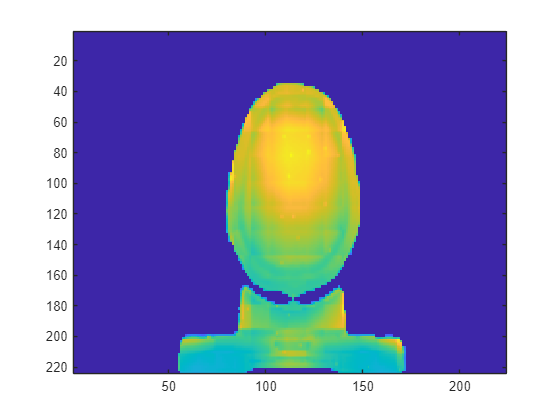

numFrames=size(volume,3);
figure(1),
for i=1:numFrames
    eximage=volume(:,:,i);
    imagesc(eximage);
    set(gca,'YDir','reverse')
    drawnow
end

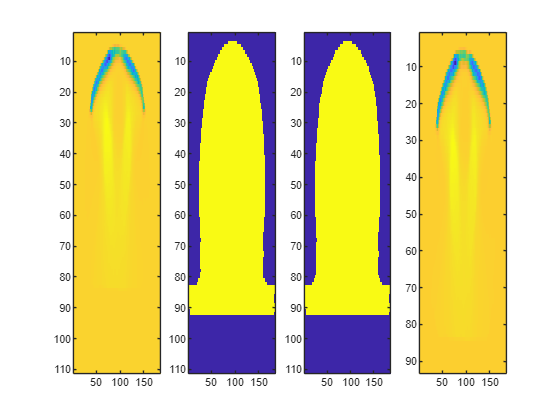

函数或变量 'Dose_ori' 无法识别。

%可视化验证
imgidx  = 55;%想要显示的层面
figure(5),  
subplot(1,4,1),imagesc(Dose_ori(:,:,imgidx));...
subplot(1,4,2),imagesc(bodyMask(:,:,imgidx));...
subplot(1,4,3),imagesc(FinalMask(:,:,imgidx));...
subplot(1,4,4),imagesc(CropDose(:,:,imgidx));

ID = "7492023001";
%可视化验证
%测试例 显示不同分类差异图像
%BODYfile
BDname = "p1-body1-"+ID+".mat";
BDfile = fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\BodyChanges', BDname);
BDTEST = load(BDfile);
BDVolume = BDTEST.cropImage; %Body变化测试图像
%BDVolume =permute(BDVolume,[2,3,1]);

%MUfile
MUname = "MU5%-"+ID+".mat";
MUfile = fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\MU', MUname);
MUTEST = load(MUfile);
MUVolume = MUTEST.cropImage; %MU测试图像
%MUVolume =permute(MUVolume,[2,3,1]);


%Gantryfile
GNname = "p1-0.4G-"+ID+".mat";
GNfile = fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\Gantry', GNname);
GNTEST = load(GNfile);
GNVolume = GNTEST.cropImage; %GN测试图像
%GNVolume =permute(GNVolume,[2,3,1]);


%MLCSfile
MLCSname = "p1-1X2F-"+ID+".mat";
MLCSfile = fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\MLCS', MLCSname);
MLCSTEST = load(MLCSfile);
MLCSVolume = MLCSTEST.cropImage; %MLC SYSTEM测试图像
%MLCSVolume =permute(MLCSVolume,[2,3,1]);


%MLCRfile
MLCRname = "p1-2X2R-"+ID+".mat";
MLCRfile = fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\MLCR', MLCRname);
MLCRTEST = load(MLCRfile);
MLCRVolume = MLCRTEST.cropImage; %MLC RADNOM测试图像
%MLCRVolume =permute(MLCRVolume,[2,3,1]);


%SETUP file
STname = "LAT-1mmR-"+ID+".mat";
STfile = fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\SETUP', STname);
STTEST = load(STfile);
STVolume =STTEST.cropImage; %SET UP测试图像
%STVolume =permute(STVolume,[2,3,1]);

%ERRORFREE file
EFname = "AAA-AXBW-"+ID+".mat";
EFfile = fullfile('E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT\ErrorFree', EFname);
EFTEST = load(EFfile);
EFVolume = EFTEST.cropImage; %SET UP测试图像
%EFVolume =permute(EFVolume,[2,3,1]);


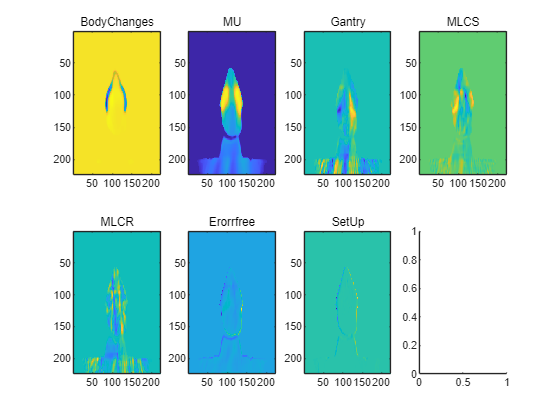

函数或变量 'ROIMask' 无法识别。

imgidx  = 90;%想要显示的层面
figure(6),  
subplot(2,4,1),imagesc(BDVolume(:,:,imgidx)),title("BodyChanges");...
subplot(2,4,2),imagesc(MUVolume(:,:,imgidx)),title("MU");...
subplot(2,4,3),imagesc(GNVolume(:,:,imgidx)),title("Gantry");...
subplot(2,4,4),imagesc(MLCSVolume(:,:,imgidx)),title("MLCS");...
subplot(2,4,5),imagesc(MLCRVolume(:,:,imgidx)),title("MLCR");...
subplot(2,4,6),imagesc(EFVolume(:,:,imgidx)),title("Erorrfree");...
subplot(2,4,7),imagesc(STVolume(:,:,imgidx)),title("SetUp");
subplot(2,4,8),imagesc(ROIMask(:,:,imgidx)),title("ROIMask");